%% PID Tuning for Robot Joints Using Control System Toolbox
% This script demonstrates PID tuning for the 7-DOF robot using
% the standard pidtune function from the Control System Toolbox.

clear; clc; close all;

% Add paths and load parameters
addpath(genpath('../functions'));
addpath(genpath('./data/generated_functions')); % Path to dynamic model functions

%% Robot Model Parameters
% These should match the parameters used in generate_dynamics.m
model_params = struct();
model_params.L_45 = 0.121851;  % Link 4-5 length (m)
model_params.L_6 = 0.1;        % Link 6 length (m)
model_params.m1 = 0.5;         % Base mass (kg)
model_params.m2 = 0.7;         % Vertical prismatic joint mass (kg)
model_params.m3 = 0.5;         % Horizontal prismatic joint mass (kg)
model_params.m4 = 0.5;         % Link 4 mass (kg)
model_params.m5 = 0.5;         % Link 5 mass (kg)
model_params.m6 = 0.3;         % Link 6 mass (kg)
model_params.m7 = 0.1;         % End effector mass (kg)
model_params.g = 9.81;         % Gravity (m/s^2)

link_lengths = [model_params.L_45; model_params.L_6];

% Simulation parameters
sample_time = 0.01;  % 100 Hz sampling rate

%% Initial PID Parameters
% Create initial PID parameters for each joint
pid_params = cell(7, 1);

% Base rotation (revolute)
pid_params{1} = struct(...
    'Kp', 100, ...
    'Ki', 5, ...
    'Kd', 10, ...
    'max_integral', 10.0, ...
    'joint_type', 'revolute');

% Vertical prismatic joint
pid_params{2} = struct(...
    'Kp', 400, ...
    'Ki', 20, ...
    'Kd', 40, ...
    'max_integral', 10.0, ...
    'joint_type', 'prismatic');

% Horizontal prismatic joint
pid_params{3} = struct(...
    'Kp', 400, ...
    'Ki', 20, ...
    'Kd', 40, ...
    'max_integral', 10.0, ...
    'joint_type', 'prismatic');

% Joint 4 (revolute)
pid_params{4} = struct(...
    'Kp', 100, ...
    'Ki', 5, ...
    'Kd', 10, ...
    'max_integral', 10.0, ...
    'joint_type', 'revolute');

% Joint 5 (revolute)
pid_params{5} = struct(...
    'Kp', 100, ...
    'Ki', 5, ...
    'Kd', 10, ...
    'max_integral', 10.0, ...
    'joint_type', 'revolute');

% Joint 6 (revolute)
pid_params{6} = struct(...
    'Kp', 100, ...
    'Ki', 5, ...
    'Kd', 10, ...
    'max_integral', 10.0, ...
    'joint_type', 'revolute');

% Joint 7 (revolute)
pid_params{7} = struct(...
    'Kp', 50, ...
    'Ki', 2, ...
    'Kd', 5, ...
    'max_integral', 10.0, ...
    'joint_type', 'revolute');

%% Step 1: Generate a test trajectory for tuning
fprintf('Generating test trajectory for controller tuning...\n');

Generating test trajectory for controller tuning...



% Generate a characteristic chess move trajectory for tuning
start_square = 'e2';
end_square = 'e4';
move_duration = 4.0;  % seconds

[q_traj, qd_traj, qdd_traj, time_vec] = generateChessTraj(start_square, end_square, link_lengths, move_duration, sample_time);

%% Step 2: Evaluate the performance of the initial controller
fprintf('\nEvaluating initial controller performance...\n');


Evaluating initial controller performance...



% Simulate with initial PID parameters
[q_init, qd_init, qdd_init, tau_init] = simulateRobotDynamicsWithJointPID(...
    q_traj, qd_traj, qdd_traj, time_vec, pid_params, model_params, struct('enabled', false));

% Calculate initial tracking error
init_error = q_traj - q_init;
init_rms_error = sqrt(mean(init_error.^2, 2));

fprintf('Initial controller RMS errors:\n');

Initial controller RMS errors:


for i = 1:7
    fprintf('  Joint %d: %.6f\n', i, init_rms_error(i));
end

  Joint 1: 0.058671
  Joint 2: 0.084637
  Joint 3: 0.015987
  Joint 4: 0.733158
  Joint 5: 1.465722
  Joint 6: 0.724777
  Joint 7: 0.795604



%% Step 3: System Identification for PID Tuning
fprintf('\nPerforming system identification for PID tuning...\n');


Performing system identification for PID tuning...



% System identification options
id_options = struct(...
    'model_order', 2, ...
    'simulation_time', 4, ...  % 5 seconds for demo
    'sample_time', sample_time);

% Identify linear models for each joint
joint_models = identifyJointModels(model_params, id_options);

System Identification for Robot Joints
--------------------------------------
Identifying model for joint 1 (revolute)...
  Model order: 2, Fit: -2.58%


Identifying model for joint 2 (prismatic)...
  Model order: 2, Fit: 78.56%


Identifying model for joint 3 (prismatic)...
  Model order: 2, Fit: 9.88%


Identifying model for joint 4 (revolute)...
  Model order: 2, Fit: 43.62%


Identifying model for joint 5 (revolute)...
  Model order: 2, Fit: 57.00%


Identifying model for joint 6 (revolute)...
  Model order: 2, Fit: 40.56%


Identifying model for joint 7 (revolute)...
  Model order: 2, Fit: 35.51%


System identification completed.



%% Step 4: PID Tuning using Control System Toolbox
fprintf('\nPerforming PID tuning using Control System Toolbox...\n');


Performing PID tuning using Control System Toolbox...



% Define joints to tune
joints_to_tune = [4, 5, 6];  % Focus on key revolute joints

% PID tuning options - different bandwidths for different joint types
bandwidths = zeros(7, 1);
bandwidths(1) = 10;   % Base rotation (medium bandwidth)
bandwidths(2) = 5;    % Vertical prismatic (lower bandwidth)
bandwidths(3) = 5;    % Horizontal prismatic (lower bandwidth)
bandwidths(4) = 15;   % Joint 4 (higher bandwidth)
bandwidths(5) = 15;   % Joint 5 (higher bandwidth)
bandwidths(6) = 15;   % Joint 6 (higher bandwidth)
bandwidths(7) = 10;   % Joint 7 (medium bandwidth)

% Setup tuning options
tuning_options = struct(...
    'joints_to_tune', joints_to_tune, ...
    'bandwidth', bandwidths, ...
    'phase_margin', 60);  % 60 degrees phase margin for robustness

% Perform PID tuning
try
    tuned_pid_params = tuneJointPIDWithPIDTune(joint_models, pid_params, tuning_options);
    
    % Simulate with tuned parameters
    [q_tuned, qd_tuned, qdd_tuned, tau_tuned] = simulateRobotDynamicsWithJointPID(...
        q_traj, qd_traj, qdd_traj, time_vec, tuned_pid_params, model_params, struct('enabled', false));
    
    % Calculate tracking error after tuning
    tuned_error = q_traj - q_tuned;
    tuned_rms_error = sqrt(mean(tuned_error.^2, 2));
    
    fprintf('\nTuned controller RMS errors:\n');
    for i = 1:7
        if ismember(i, joints_to_tune)
            fprintf('  Joint %d: %.6f (tuned)\n', i, tuned_rms_error(i));
        else
            fprintf('  Joint %d: %.6f\n', i, tuned_rms_error(i));
        end
    end
catch ME
    warning('PID tuning failed: %s', ME.message);
    tuned_pid_params = pid_params;
    q_tuned = q_init;
    tuned_error = init_error;
    tuned_rms_error = init_rms_error;
end

Tuning joint 4 (revolute) with pidtune...
Joint 4 tuned successfully: Kp=2.73, Ki=10.66, Kd=0.05
  Rise time: 0.107 s, Settling time: 0.340 s, Overshoot: 10.51%


Tuning joint 5 (revolute) with pidtune...
Joint 5 tuned successfully: Kp=6.72, Ki=47.21, Kd=0.00
  Rise time: 0.101 s, Settling time: 0.502 s, Overshoot: 9.64%


Tuning joint 6 (revolute) with pidtune...
Joint 6 tuned successfully: Kp=4.45, Ki=22.23, Kd=0.00
  Rise time: 0.107 s, Settling time: 0.587 s, Overshoot: 8.44%


PID tuning completed for 3 joints.



Tuned controller RMS errors:


  Joint 1: 0.032071
  Joint 2: 0.084662
  Joint 3: 0.008187


  Joint 4: 0.746979 (tuned)
  Joint 5: 1.436016 (tuned)
  Joint 6: 0.731779 (tuned)


  Joint 7: 0.804373



%% Step 5: Compare Controller Performance
fprintf('\nComparing controller performance...\n');


Comparing controller performance...


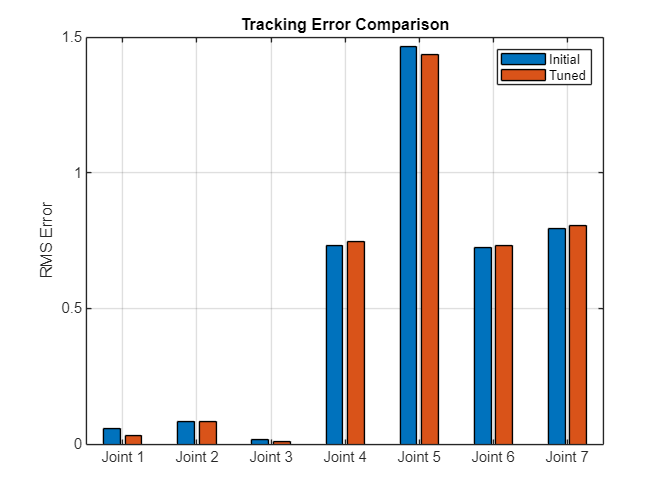


% RMS tracking error comparison
figure('Name', 'RMS Tracking Error Comparison', 'Position', [100, 100, 800, 600]);
bar([init_rms_error, tuned_rms_error]);
set(gca, 'XTickLabel', {'Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'Joint 6', 'Joint 7'});
legend('Initial', 'Tuned');
ylabel('RMS Error');
title('Tracking Error Comparison');
grid on;

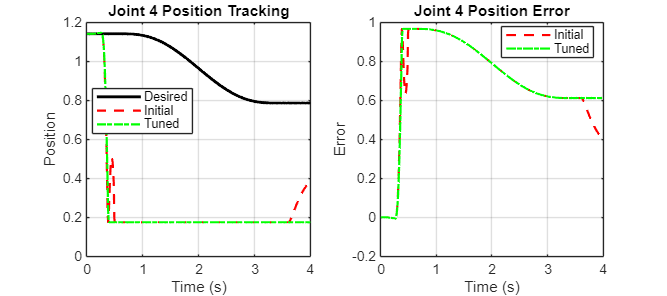

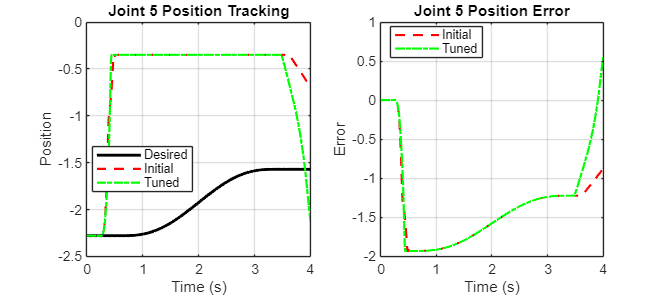

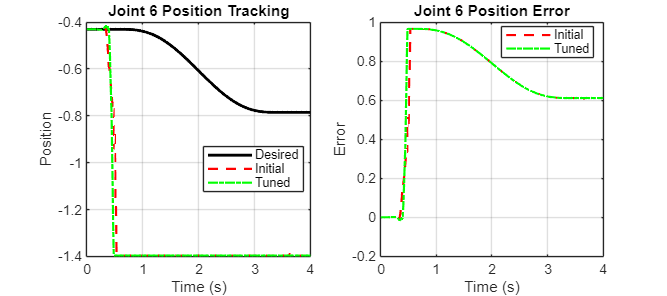


% Joint position tracking comparison for tuned joints
for j = joints_to_tune
    figure('Name', sprintf('Joint %d Position Tracking Comparison', j), 'Position', [150, 150, 900, 400]);
    
    % Position tracking
    subplot(1, 2, 1);
    plot(time_vec, q_traj(j,:), 'k-', 'LineWidth', 2, 'DisplayName', 'Desired');
    hold on;
    plot(time_vec, q_init(j,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Initial');
    plot(time_vec, q_tuned(j,:), 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Tuned');
    title(sprintf('Joint %d Position Tracking', j));
    xlabel('Time (s)');
    ylabel('Position');
    legend('Location', 'best');
    grid on;
    
    % Position error
    subplot(1, 2, 2);
    plot(time_vec, init_error(j,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Initial');
    hold on;
    plot(time_vec, tuned_error(j,:), 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Tuned');
    title(sprintf('Joint %d Position Error', j));
    xlabel('Time (s)');
    ylabel('Error');
    legend('Location', 'best');
    grid on;
end

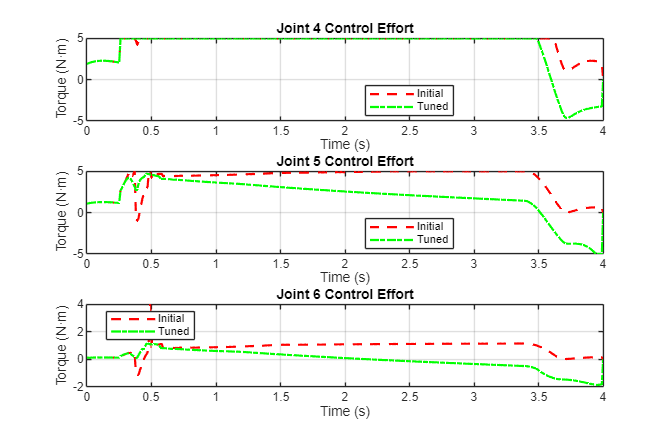


% Control effort comparison for tuned joints
figure('Name', 'Control Effort Comparison', 'Position', [200, 200, 900, 600]);
for i = 1:length(joints_to_tune)
    j = joints_to_tune(i);
    
    subplot(length(joints_to_tune), 1, i);
    plot(time_vec, tau_init(j,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Initial');
    hold on;
    plot(time_vec, tau_tuned(j,:), 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Tuned');
    title(sprintf('Joint %d Control Effort', j));
    xlabel('Time (s)');
    ylabel('Torque (N·m)');
    legend('Location', 'best');
    grid on;
end


%% Step 6: Disturbance Rejection Test
fprintf('\nTesting disturbance rejection...\n');


Testing disturbance rejection...


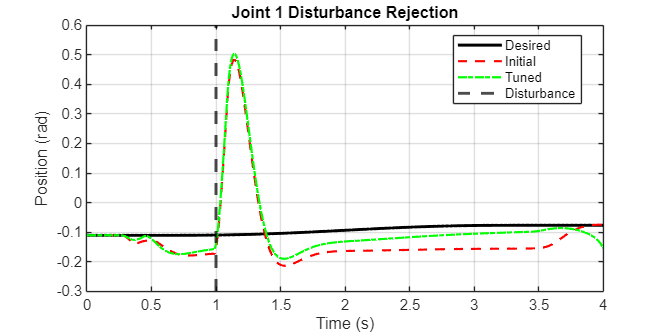


% Define disturbance
disturbance = struct(...
    'enabled', true, ...
    'time', 1.0, ...     % Apply at 1 second
    'joint', 1, ...      % Apply to base joint
    'magnitude', 10);    % Large torque disturbance

% Test disturbance rejection with each controller
[q_init_dist, ~, ~, ~] = simulateRobotDynamicsWithJointPID(...
    q_traj, qd_traj, qdd_traj, time_vec, pid_params, model_params, disturbance);

[q_tuned_dist, ~, ~, ~] = simulateRobotDynamicsWithJointPID(...
    q_traj, qd_traj, qdd_traj, time_vec, tuned_pid_params, model_params, disturbance);

% Plot disturbance rejection performance
figure('Name', 'Disturbance Rejection Comparison', 'Position', [250, 250, 800, 400]);
plot(time_vec, q_traj(1,:), 'k-', 'LineWidth', 2, 'DisplayName', 'Desired');
hold on;
plot(time_vec, q_init_dist(1,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Initial');
plot(time_vec, q_tuned_dist(1,:), 'g-.', 'LineWidth', 1.5, 'DisplayName', 'Tuned');
xline(disturbance.time, 'k--', 'LineWidth', 2, 'DisplayName', 'Disturbance');
title('Joint 1 Disturbance Rejection');
xlabel('Time (s)');
ylabel('Position (rad)');
legend('Location', 'best');
grid on;


%% Step 7: Visualize Chess Move with Tuned Controller
fprintf('\nVisualizing chess move with tuned controller...\n');


Visualizing chess move with tuned controller...


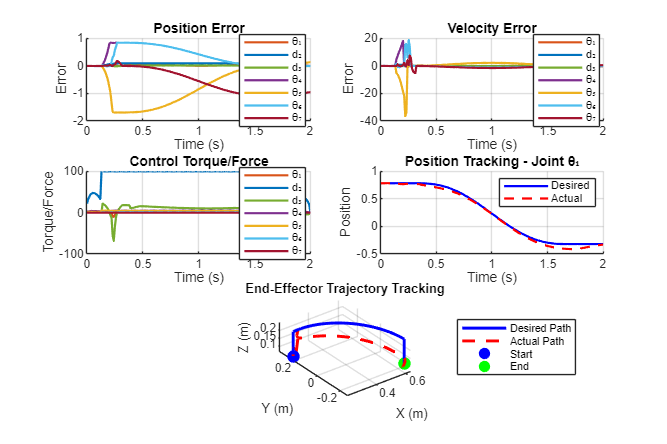

Controller Performance Metrics:
Max End-Effector Error: 0.1842 m
Mean End-Effector Error: 0.0975 m
RMS End-Effector Error: 0.1057 m

Maximum Position Errors:
Joint θ₁: 5.32 deg
Joint d₂: 0.0950 m
Joint d₃: 0.0172 m
Joint θ₄: 48.54 deg
Joint θ₅: 97.09 deg
Joint θ₆: 48.54 deg
Joint θ₇: 63.43 deg



% Generate a full chess move trajectory
start_square = 'a1';
end_square = 'h8';
move_duration = 2.0;  % seconds
clear q_chess qd_chess qdd_chess t_chess
[q_chess, qd_chess, qdd_chess, t_chess] = generateChessTraj(...
    start_square, end_square, link_lengths, move_duration, sample_time);

% Simulate with the tuned controller
[q_chess_actual, qd_chess_actual, qdd_chess_actual, tau_chess] = simulateRobotDynamicsWithJointPID(...
    q_chess, qd_chess, qdd_chess, t_chess, tuned_pid_params, model_params, struct('enabled', false));

% Visualize the performance
visualizeControlPerformance(t_chess, q_chess, qd_chess, qdd_chess, ...
    q_chess_actual, qd_chess_actual, qdd_chess_actual, tau_chess, link_lengths);

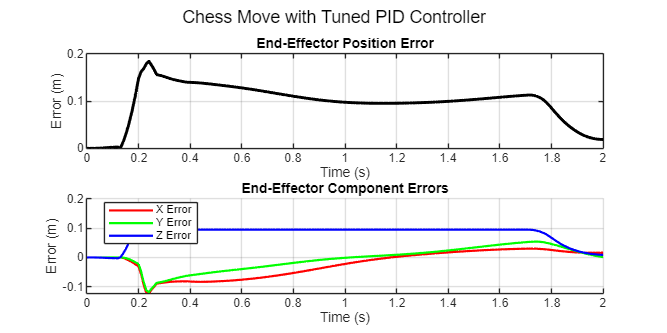

sgtitle('Chess Move with Tuned PID Controller');

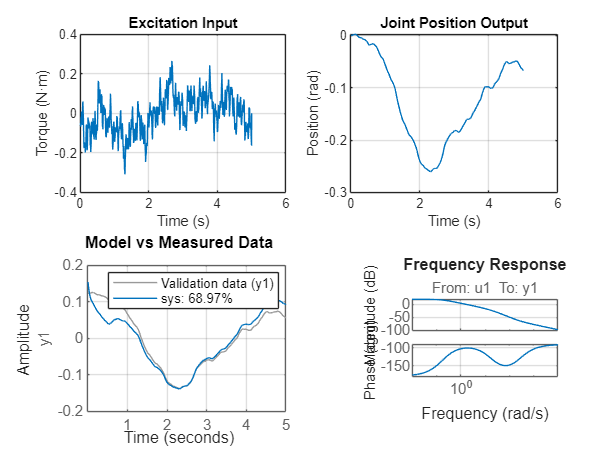

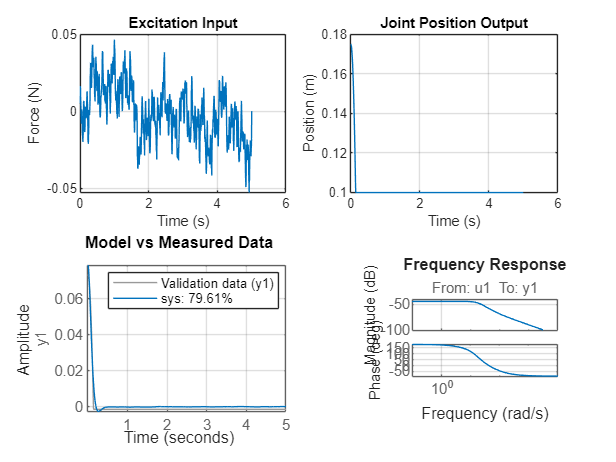

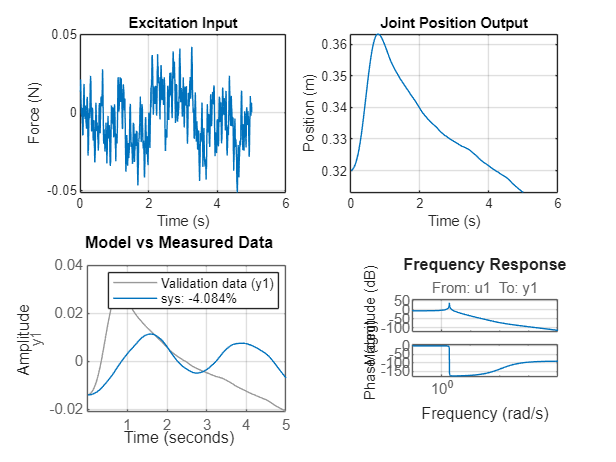

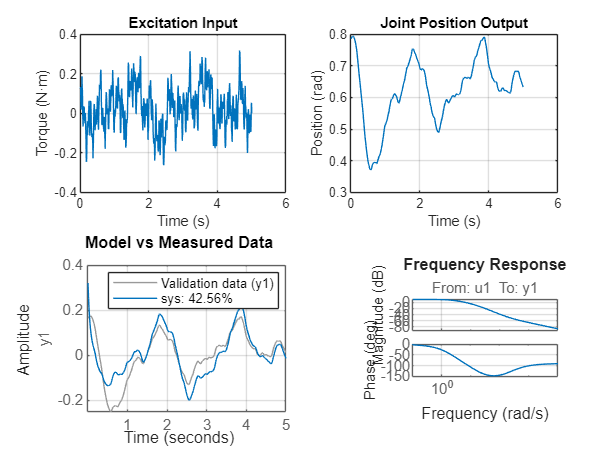

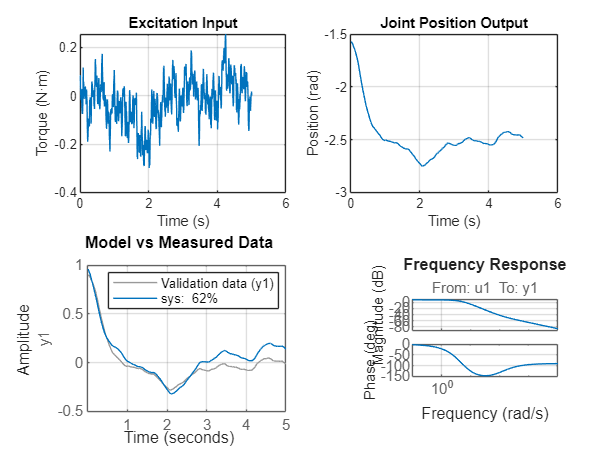

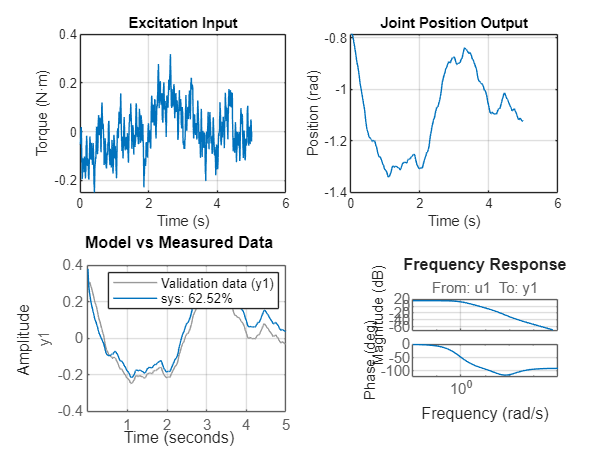

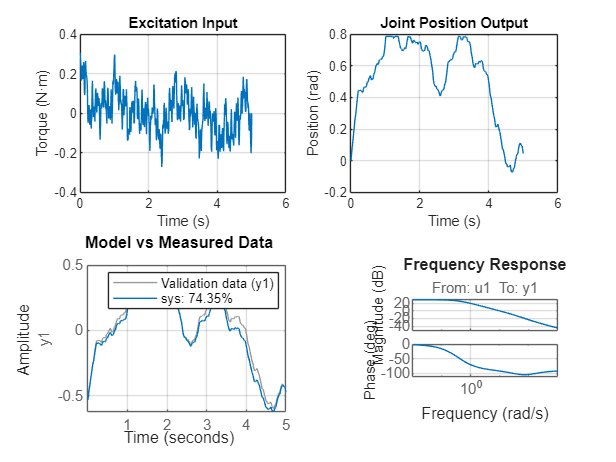

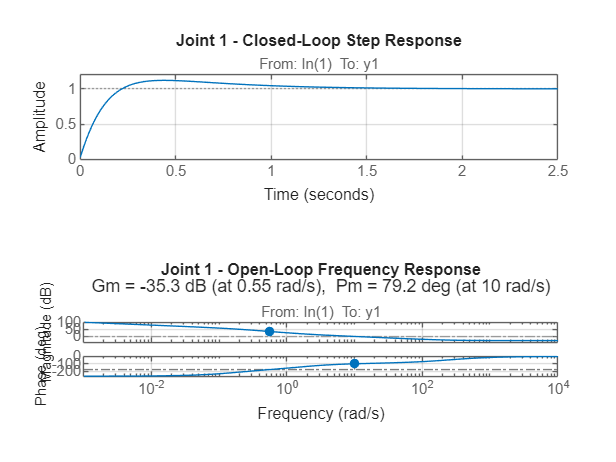


PID Controller Tuning Tests Completed



% Visualize the trajectory itself
chess_params = struct('show_board', true, 'square_size', 0.06, 'board_offset', [0.18; 0.24; 0]);
visualizeTrajectory(q_chess_actual, qd_chess_actual, qdd_chess_actual, t_chess, link_lengths, chess_params);
title(sprintf('Chess Move: %s to %s with Tuned PID Controller', start_square, end_square));

fprintf('\nPID Controller Tuning Tests Completed\n');